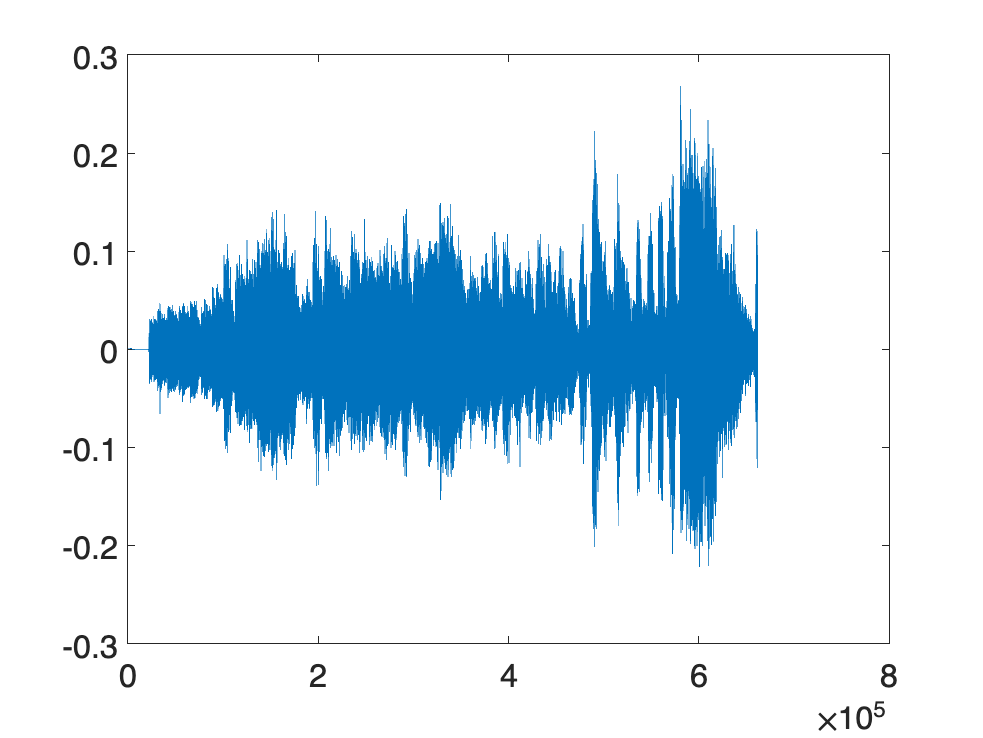

%The following reads the data file, and plots the file
[y,Fs] = audioread('PinkPanther30.wav');

%Because the sound signals have 2 channels, we will just analyze the first channel
y = y(:,1);

figure(1)
plot(y)
set(gca,'fontsize',18)

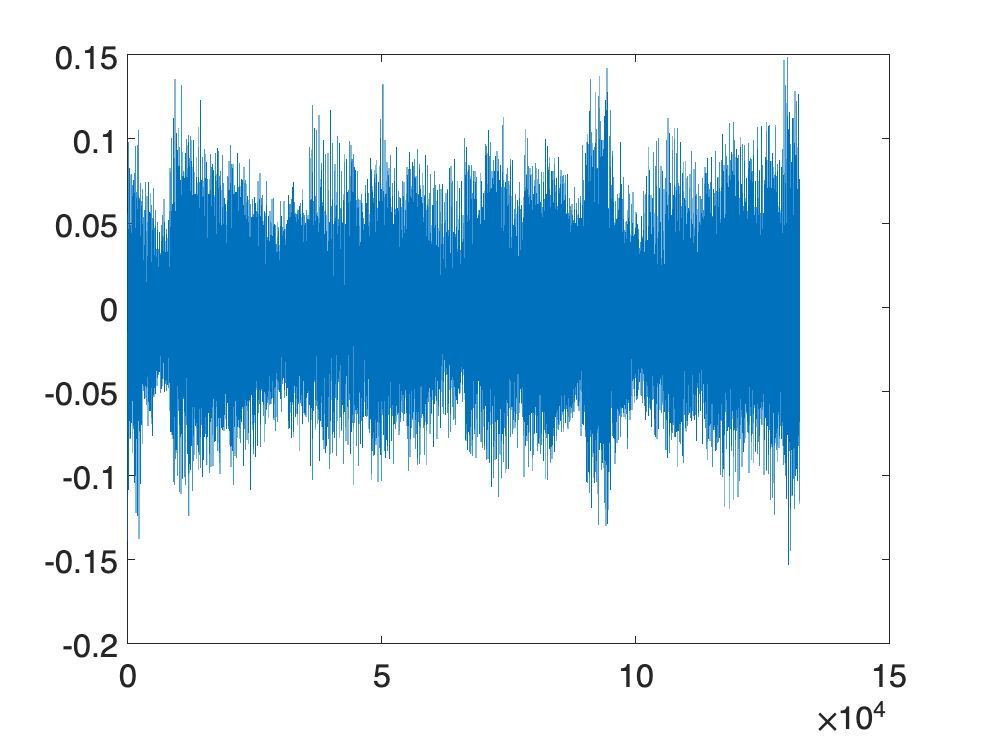


% Find the length of y
L = length(y);


% Determine starting and ending points of your clipping by looking at plot 1
% Note these must be integers that are not 0!
index1 = round(L*0.3); % CHANGE THIS NUMBER
index2 = round(L*0.5); % CHANGE THIS NUMBER

sound(y(index1:index2),Fs)  % Play the file
newsignal = y(index1:index2);  % Clips sound signal to new signal that starts at index1 and goes to index2
figure(2)
plot(newsignal)
set(gca,'fontsize',18)

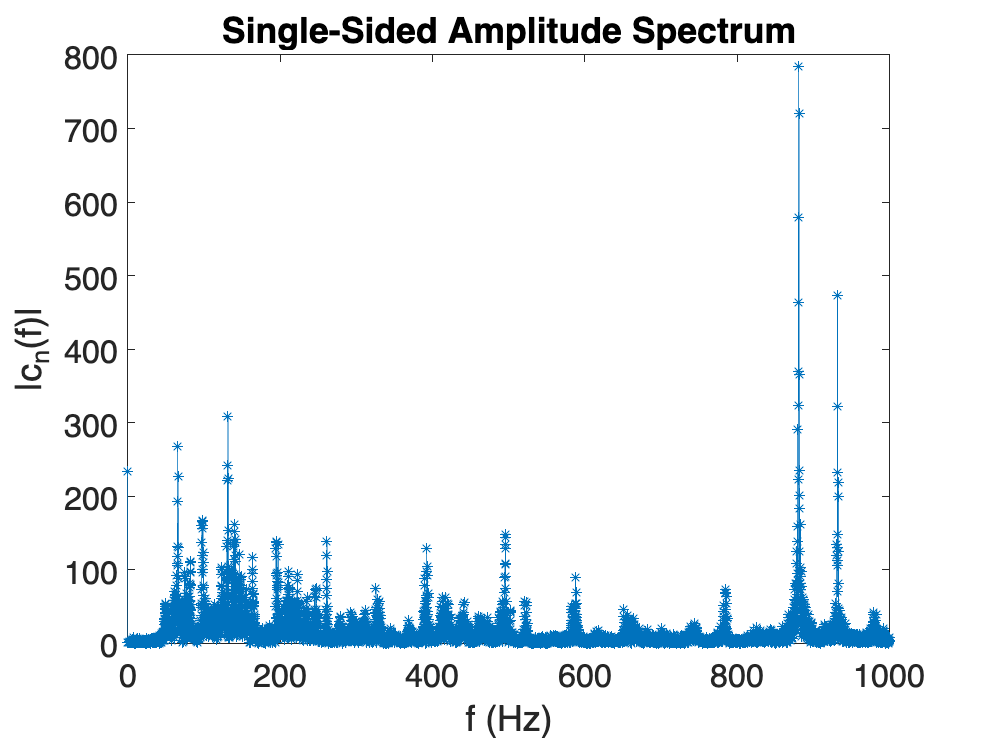

[signal,Fs] = audioread('PinkPanther30.wav');
signal = signal(:,1);
L = length(signal);
signal = signal(round(L*0.3):round(L*0.5));

% Copy the procedure in the video to get the single sided spectrum
y=fft(signal);
yMag = abs(y);
N=length(yMag);
f=0:(Fs/N):(Fs/2);
yMag=yMag(1:length(f));
% This code plots yMag as a function of f
% You can comment out this code if necessary while building your solution
figure
plot(f,yMag,'-*');
title('Single-Sided Amplitude Spectrum')
xlabel('f (Hz)')
ylabel('|c_n(f)|')
set(gca,'fontsize',18)
xlim([0,1000])

url = 'https://courses.edx.org/asset-v1:MITx+18.03Fx+3T2018+type@asset+block@audio_1803_musicdata_clarinet1.wav';
websave('1803_musicdata_clarinet1.wav', url);
url = 'https://courses.edx.org/asset-v1:MITx+18.03Fx+3T2018+type@asset+block@audio_1803_musicdata_guitar1.wav';
websave('1803_musicdata_guitar1.wav', url);
url = 'https://courses.edx.org/asset-v1:MITx+18.03Fx+3T2018+type@asset+block@audio_1803_musicdata_voice1.wav';
websave('1803_musicdata_voice1.wav', url);

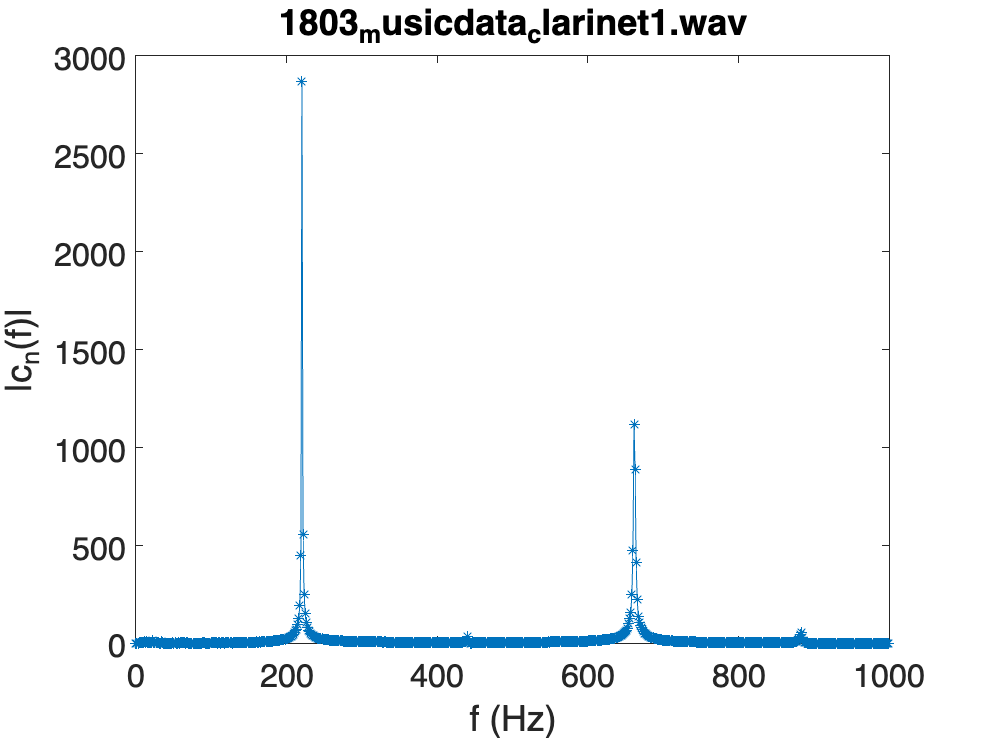

show_spectrum('1803_musicdata_clarinet1.wav', 1);

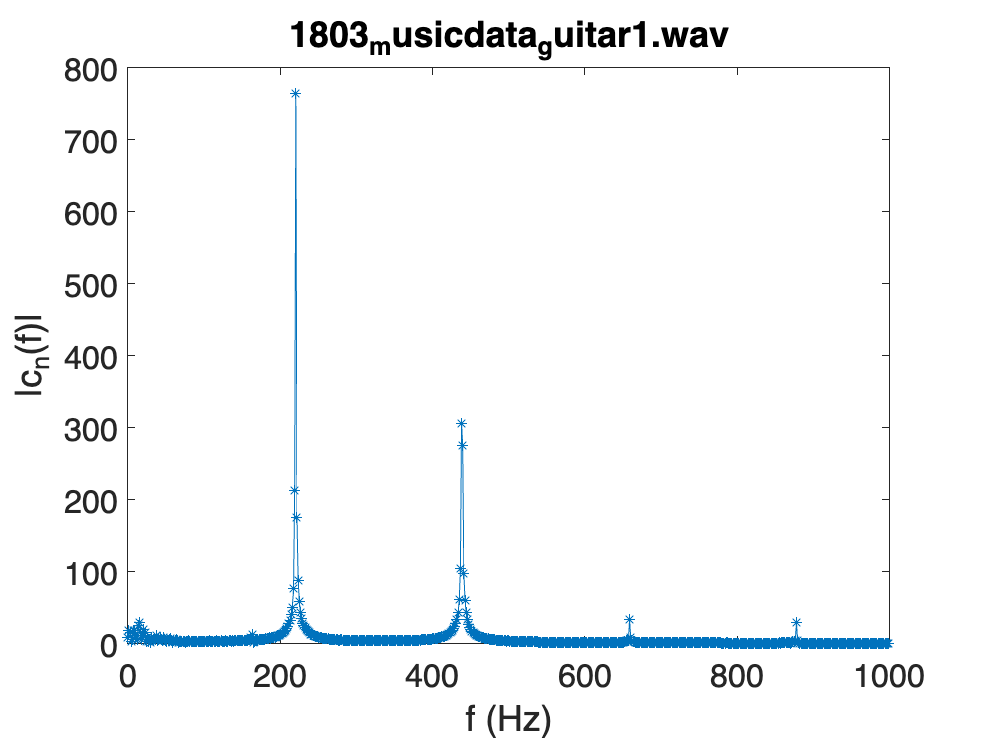

show_spectrum('1803_musicdata_guitar1.wav', 2);

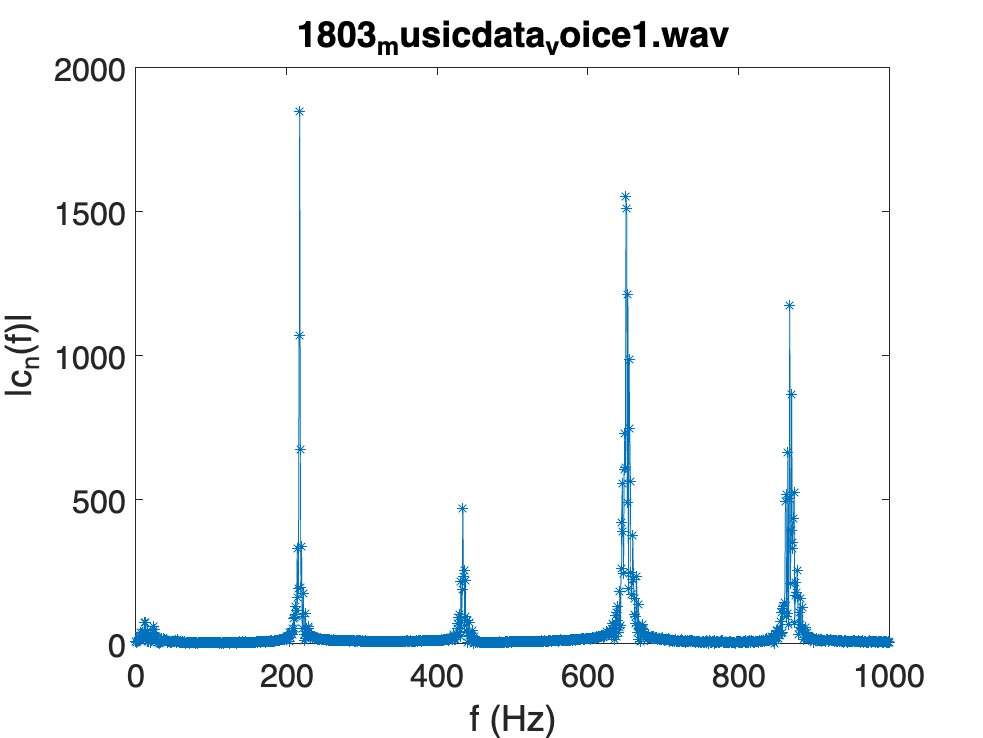

show_spectrum('1803_musicdata_voice1.wav', 3);


function res = show_spectrum(filename, i)

    [signal,Fs] = audioread(filename);
    signal = signal(:,1);
    Len = length(signal);
    signal = signal(round(Len*0.3):round(Len*0.5));
    L = length(signal);
                      
    y = fft(signal);
    yMag = abs(y);
    N = length(yMag);
    f = 0: (Fs/N) : (Fs/2);
    yMag = yMag(1:length(f));
    
    figure(i)
    p = plot(f,yMag,'-*');
    title(filename)
    xlabel('f (Hz)')
    ylabel('|c_n(f)|')
    set(gca,'fontsize',18)
    xlim([0,1000])
    res = p;
end


